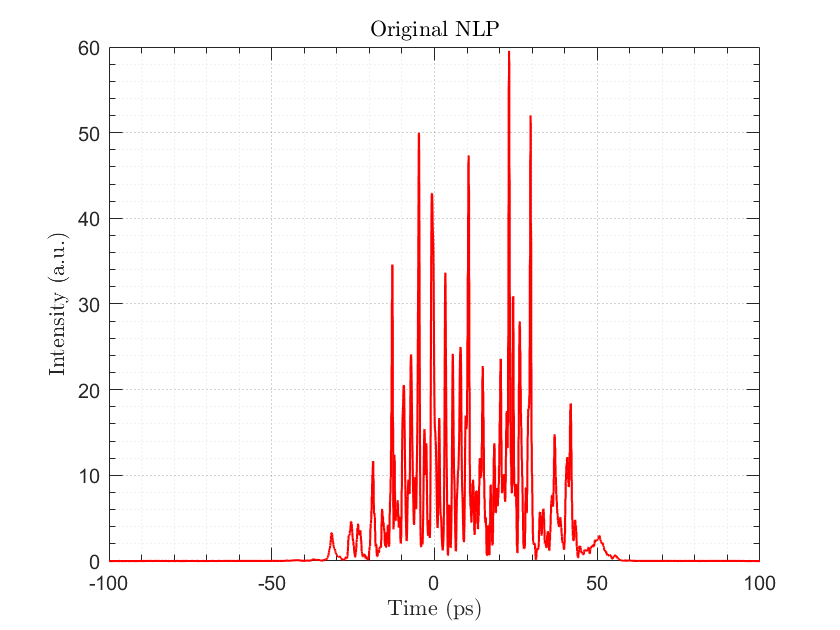

clear
clf
close all 
cd 'C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data';

% ============= NLP Data =============== %
nlpulse = readmatrix("Pulse.txt");
t_ps = nlpulse(:,1)*1e12;

E_N = nlpulse(:,2) + 1j*nlpulse(:,3); 
E_P = nlpulse(:,4) + 1j*nlpulse(:,5);

I_T = abs(E_P).^2 + abs(E_N).^2;

% ====================================== %

% ============= Linear scale plots =============== %
plot(t_ps,I_T, "Color", [1 0 0], 'LineWidth', 1.05)
title('Original NLP',"Interpreter","latex");
xlabel('Time (ps)', "Interpreter","latex");
ylabel('Intensity (a.u.)',"Interpreter","latex");
box on
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid
hold off

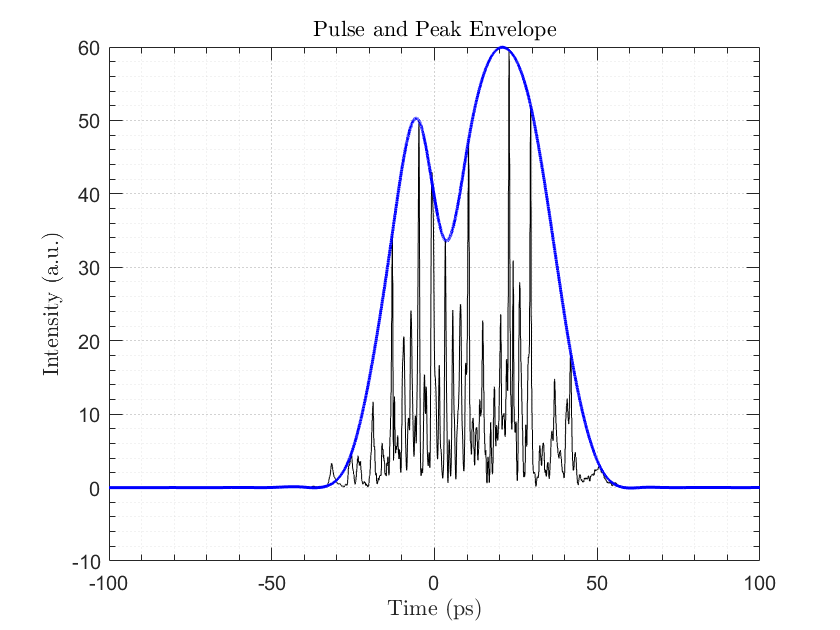


% 'peak' method with a sliding window of N points:
[upper_env, lower_env] = envelope(I_T, 512, 'peak');

figure()
plot(t_ps, I_T, 'Color',[0 0 0]); hold on
plot(t_ps, upper_env, 'b', 'LineWidth',1.5);
xlabel('Time (ps)','Interpreter','latex');
ylabel('Intensity (a.u.)','Interpreter','latex');
title('Pulse and Peak Envelope','Interpreter','latex');
box on
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid

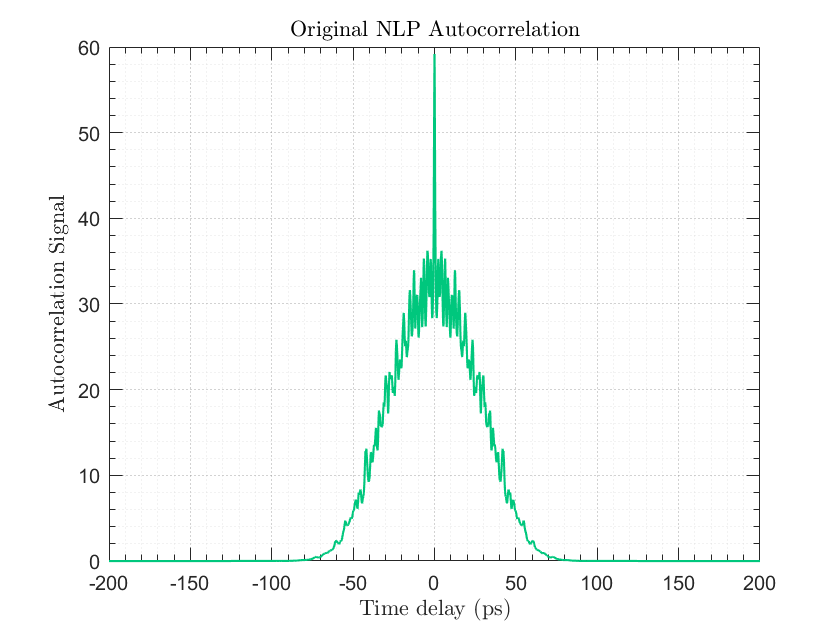



% =============== Auto correlation ================== %
% Compute the sample‐spacing (in ps) lags → time:
dt = mean(diff(t_ps));  

% Compute autocorrelation:
[acf, lags] = xcorr(I_T, 'biased');  

% Convert lag indices to physical lag times (in ps):
lags_time = lags * dt;  

%Plot:
figure()
plot(lags_time, acf, 'LineWidth', 1.05, 'Color', '#00c77d');
xlabel('Time delay (ps)', 'Interpreter','latex');
ylabel('Autocorrelation Signal', 'Interpreter','latex');
title('Original NLP Autocorrelation', 'Interpreter','latex');
box on
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid

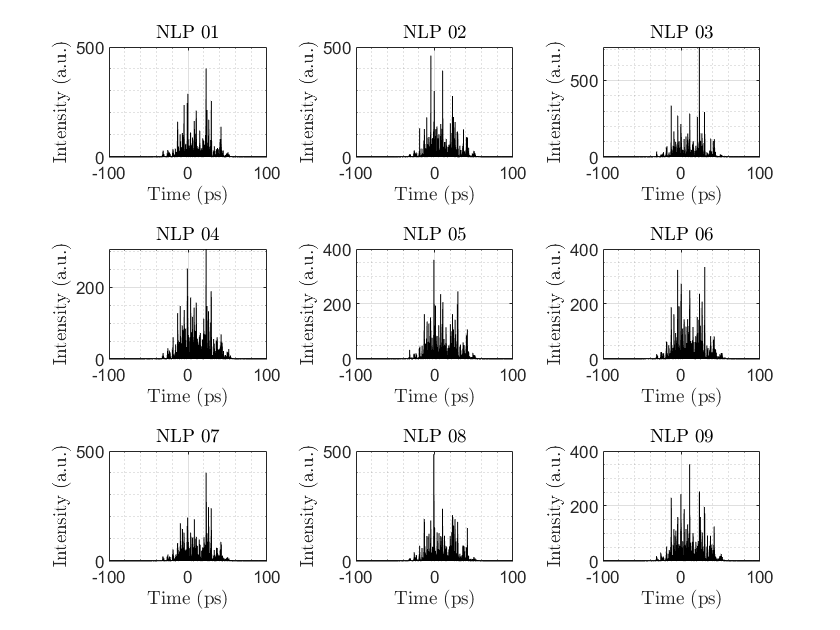

% ============= New NLP's =============== %
M = 9; 
sigma = 1;
mu = 0;
[NLP_Pos, NLP_Neg] = deriveNLPs(E_P, E_N, sigma, mu, M, t_ps, 'shuffle');
dt = mean(diff(t_ps));       % sample spacing in ps
figure(3);
tiledlayout(3,3,'TileSpacing','compact');

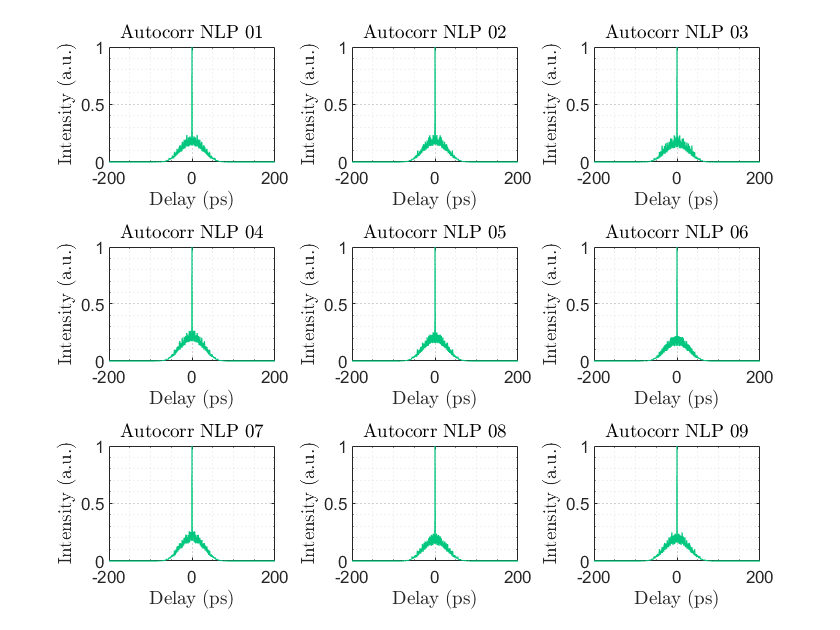


for k = 1:M
    % retrieve the k-th pulse intensity
    I_k = abs(NLP_Pos(:,k)).^2 + abs(NLP_Neg(:,k)).^2;

    % autocorrelation 
    [acf, lags] = xcorr(I_k, 'coeff');
    tau = lags * dt;  % convert lags to ps

    nexttile;
    plot(tau, acf, 'LineWidth',0.65,'Color','#00c77d');
    title(sprintf('Autocorr NLP 0%d',k),'Interpreter','latex');
    xlabel('Delay (ps)','Interpreter','latex');
    ylabel('Intensity (a.u.)','Interpreter','latex');
    grid on
    set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
    'TickLength', [0.02, 0.04], ...
    'LineWidth', 0.5);
    grid minor; % Adds minor grid lines
    set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
             'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
             'GridAlpha', 0.7, ...         % Transparency of major grid
             'MinorGridLineStyle', ':', ...% Dotted minor grid lines
             'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
             'MinorGridAlpha', 0.5);       % Transparency of minor grid
end


% for i = 1:M
%     fname = sprintf('NLPx%d.csv', i);
%     SvNLP = [t_ps, NLP_Neg(:,i), NLP_Pos(:,i)];
%     writematrix(SvNLP, fname)
% end
% =========================================== %




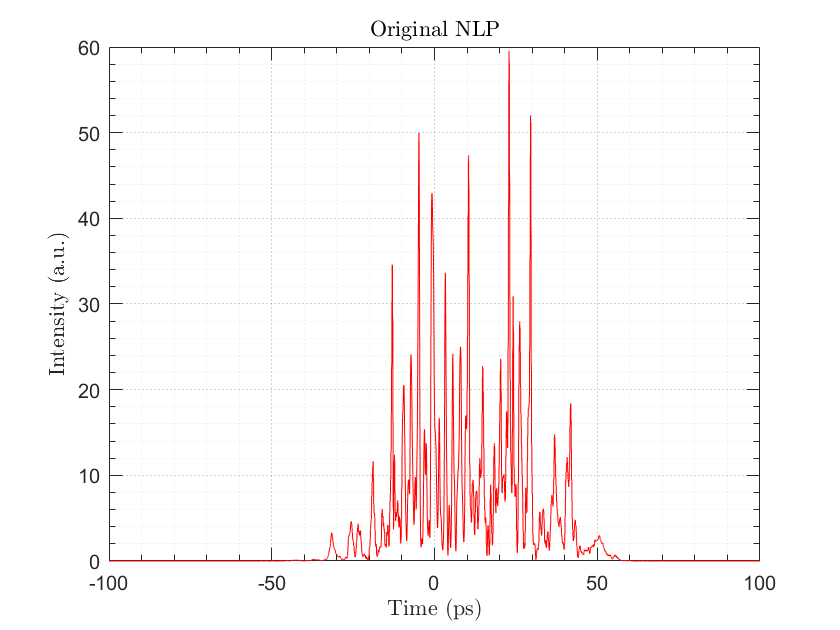

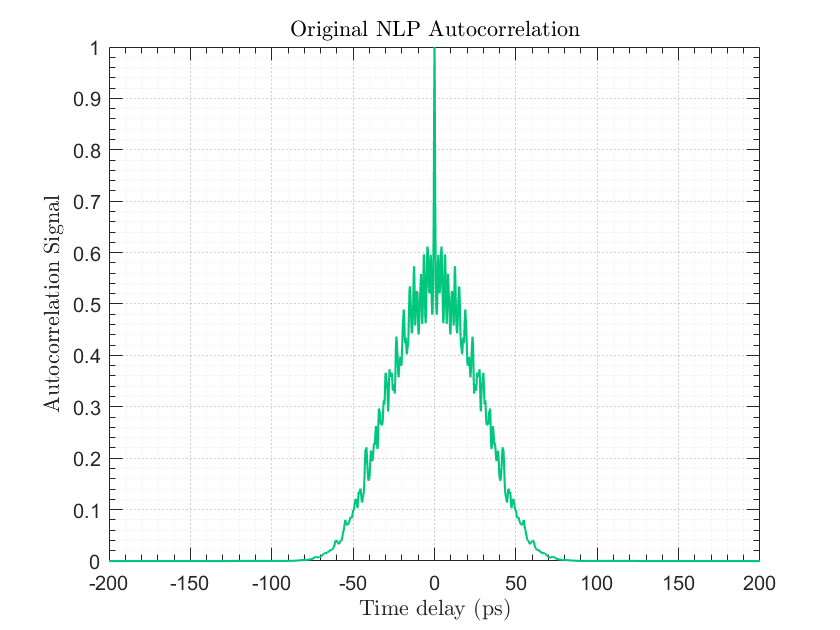

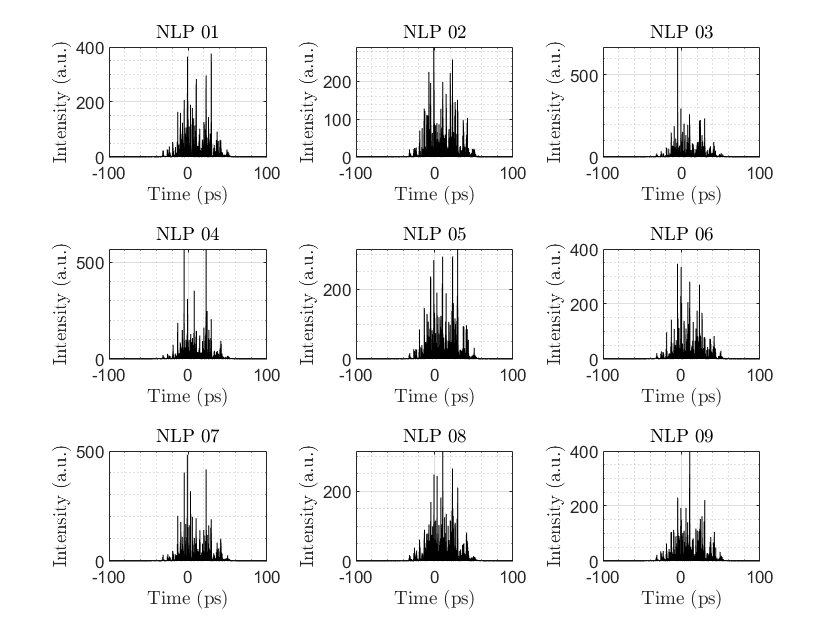

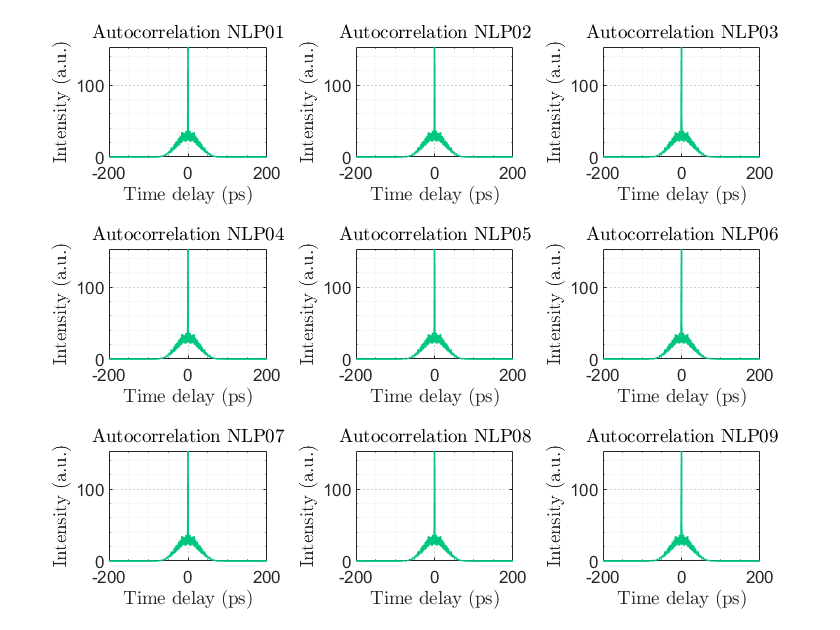

function [NLP_Pos, NLP_Neg] = deriveNLPs(E_P, E_N, sigma, mu, M, t_ps, seed)

% deriveNLPs  Genera M nuevos pulsos tipo Noise-Like (NLP) a partir de
%             componentes E(+) y E(–) originales y los grafica.
%
%   [NLP_Pos, NLP_Neg] = deriveNLPs(E_P,E_N,sigma,mu,M)
%   [NLP_Pos, NLP_Neg] = deriveNLPs(E_P,E_N,sigma,mu,M,t_ps)

    arguments
        E_P (:,1)  {mustBeNumeric}
        E_N (:,1)  {mustBeNumeric}
        sigma (1,1) double
        mu    (1,1) double
        M     (1,1) {mustBeInteger,mustBePositive}
        t_ps  (:,1) double = (0:numel(E_P)-1).'   
        seed  double = NaN
    end
    
     if ~isnan(seed)          
        if isequal(seed,'shuffle')
            rng('shuffle');
        else
            rng(seed);     
        end
    end
    
    % Pre-allocate
    N  = numel(E_P);
    NLP_Pos = zeros(N, M);
    NLP_Neg = zeros(N, M);

    %% NLP Generation, Autocorrelation and Plotting
    figure()
    tiledlayout(3,3)
    for k = 1:M
        % ------------ Random gain factor --------------
        g_k = sigma * randn(N,1) + mu;

        % ------------ New NLPs --------------------
        NLP_Pos(:,k) = E_P .* g_k;
        NLP_Neg(:,k) = E_N .* g_k;

        % ------------ Intensities ---------------------
        I_total = abs(NLP_Pos(:,k)).^2 + abs(NLP_Neg(:,k)).^2;

        %% ---------- Plotting  ----------------------------
        nexttile(k)
        plot(t_ps, I_total, "Color", [0 0 0]); hold on
        title(sprintf('NLP 0%d', k), 'Interpreter','latex')
        xlabel('Time (ps)','Interpreter','latex'); ylabel('Intensity (a.u.)','Interpreter','latex')
        grid on; box on
        set(gca,'XMinorTick','on','YMinorTick','on',...
                'TickLength',[0.02 0.04],'LineWidth',0.5)
        grid minor

    end
    
end


